gscatter(metrics1(:,3), metrics1(:,4), players1,'rgb','osd');
xlabel('Saves');
ylabel('Tackles');
N = size(metrics1,1);
lda1 = fitcdiscr(metrics1(:,3:4),players1);
ldaClass = resubPredict(lda1);
ldaResubErr = resubLoss(lda1);
[ldaResubCM_s,grpOrder_s] = confusionmat(players1,ldaClass)

ldaResubCM_s =     11     0
     2     9


grpOrder_s = 2×1 cell array
    {'Drogba'}
    {'Petr'  }


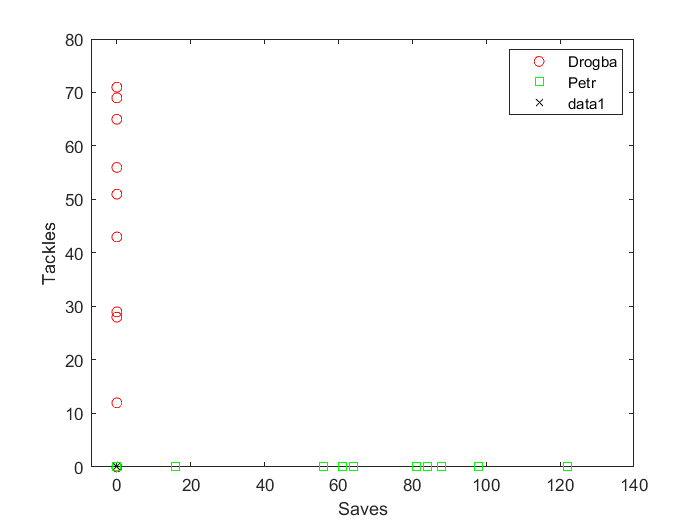

bad = ~strcmp(ldaClass,players1);
hold on;
plot(metrics1(bad,3), metrics1(bad,4), 'kx');
hold off;

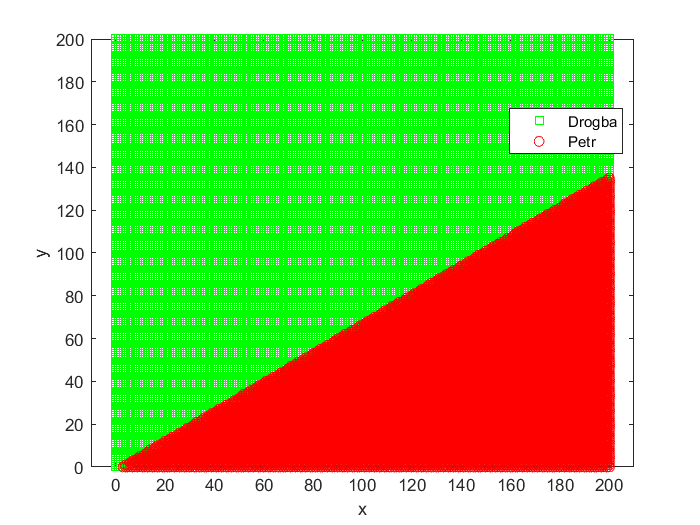

[x,y] = meshgrid(0:200,0:200);
x = x(:);
y = y(:);
j = classify([x y],metrics1(:,3:4),players1);
gscatter(x,y,j,'grb','sod')